n = 10;                                  % Size of maze
maze = -50*ones(n,n);                   % Random generate path
for i=1:(n-3)*n
    maze(randi([1,n]),randi([1,n]))=1;
end
maze(1,1) = 1;                          % Starting node
maze(n,n) = 10;                         % Goal
disp(maze)

     1     1     1     1   -50     1   -50     1     1     1
   -50   -50   -50     1   -50     1     1     1   -50     1
     1     1     1     1   -50   -50     1   -50   -50   -50
   -50     1   -50   -50   -50     1     1     1     1     1
   -50     1     1   -50     1     1   -50     1   -50     1
   -50   -50     1   -50   -50   -50   -50     1   -50     1
     1     1     1     1     1     1     1     1   -50     1
     1   -50     1   -50     1     1   -50     1   -50     1
     1   -50   -50     1   -50     1   -50     1   -50   -50
     1     1     1     1     1     1   -50     1     1    10



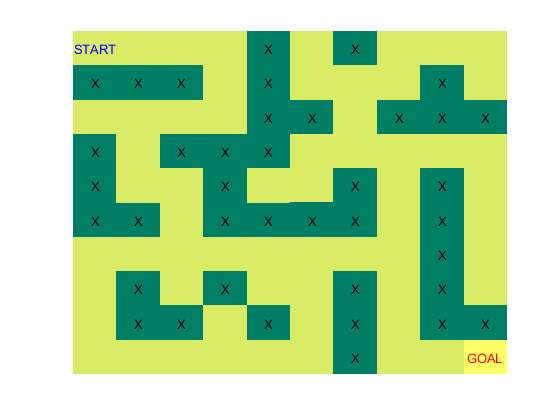

% Visualizing Maze
n=length(maze);
figure
imagesc(maze)
colormap(summer)
for i=1:n
    for j=1:n
        if maze(i,j)==min(maze)
            text(j,i,'X','HorizontalAlignment','center')
        end
    end
end
text(1,1,'START','HorizontalAlignment','center', 'Color', 'blue')
text(n,n,'GOAL','HorizontalAlignment','center', 'Color', 'red')
axis off

Goal=n*n;
fprintf('Goal State is: %d',Goal)

Goal State is: 100

% Reward System
% Up = (i-n);            % Possible Directions to take
% Down = (i+n);
% Left = (i-1);
% Right = (i+1);
% D_SE = (i+n+1);
% D_SW = (i+n-1);
% D_NE = (i-n+1);
%D_NW = (i-n-1);

reward=zeros(n*n);
for i=1:Goal
    reward(i,:)=reshape(maze',1,Goal);
end
for i=1:Goal
    for j=1:Goal
        if j~=i-n  && j~=i+n  && j~=i-1 && j~=i+1 && j~=i+n+1 && j~=i+n-1 && j~=i-n+1 && j~=i-n-1
            reward(i,j)=-Inf;
        end    
    end
end
for i=1:n:Goal
    for j=1:i+n
        if j==i+n-1 || j==i-1 || j==i-n-1
            reward(i,j)=-Inf;
            reward(j,i)=-Inf;
        end
    end
end

% Q-Learning Algorithm
q = randn(size(reward));        % Initialize Q-Maxtix set goal state
gamma = 0.9;                    % Discount Factor
alpha = 0.2;                    % Learning Rate
maxItr = 50;                    % Max iteration

for i=1:maxItr
    currentState=1;                                                                % Starting from start position
    while(1)                                                                       % Repeat until Goal state is reached
    n_actions = find(reward(currentState,:)>0);                                    % possible actions for the chosen state
    nextState = n_actions(randi([1 length(n_actions)],1,1));                       % choose an action at random and set it as the next state
        n_actions = find(reward(nextState,:)>=0);                                  % find all the possible actions for the selected state
        max_q = 0;                                                                 % find the maximum q-value i.e, next state with best action
        for j=1:length(n_actions)
            max_q = max(max_q,q(nextState,n_actions(j)));
        end
        q(currentState,nextState)=reward(currentState,nextState)+gamma*max_q;      % Update q-values as per Bellman's equation
        if(currentState == Goal)                                                   % Check whether the episode has completed i.e Goal has been reached
            break;
        end
        currentState=nextState;                                                    % Set current state as next state
    end
end
% Solving the Maze
start = 1;
move = 0;
path = start;

while(move~=Goal)
    [~,move]=max(q(start,:));
    if ismember(move,path)                        % Deleting chances of getting stuck in small loops  (upto order of 4)
        [~,x]=sort(q(start,:),'descend');
        move=x(2);
        if ismember(move,path)
            [~,x]=sort(q(start,:),'descend');
            move=x(3);
            if ismember(move,path)
                [~,x]=sort(q(start,:),'descend');
                move=x(4);
                if ismember(move,path)
                    [~,x]=sort(q(start,:),'descend');
                    move=x(5);
                end
            end
        end
    end
    path=[path,move];                             % Appending next action/move to the path
    start=move;
end

% Solution of Maze
fprintf('Final path: %s',num2str(path))

Final path: 1    2    3   14   23   32   42   53   64   75   66   67   78   88   99  100

fprintf('Total steps: %d',length(path))

Total steps: 16

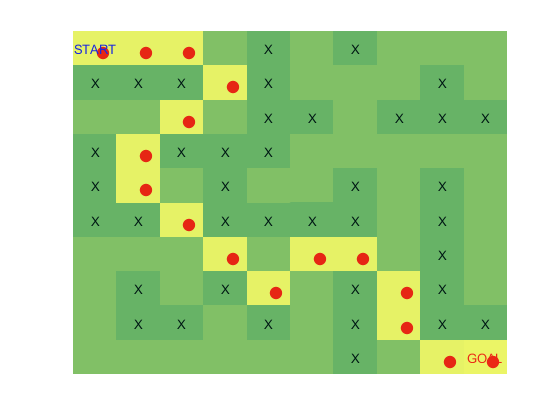

pmat=zeros(n,n);                                  % reproducing path to matrix path
[q, r]=quorem(sym(path),sym(n));
q=double(q);r=double(r);
q(r~=0)=q(r~=0)+1;r(r==0)=n;
for i=1:length(q)
    pmat(q(i),r(i))=50;
end
figure                                            % Final Plot of the maze
imagesc(pmat)
colormap(white)
for i=1:n
    for j=1:n
        if maze(i,j)==min(maze)
            text(j,i,'X','HorizontalAlignment','center')
        end
        if pmat(i,j)==50
            text(j,i,'\bullet','Color','red','FontSize',24)
        end
    end
end
text(1,1,'START','HorizontalAlignment','center', 'Color', 'blue')
text(n,n,'GOAL','HorizontalAlignment','center', 'Color', 'red')
hold on
imagesc(maze,'AlphaData',0.2)
colormap(summer)
hold off
axis off